T = [0.5 1 2 3 4 5 7 9];
U = [6.36 6.48 7.26 8.22 8.66 8.99 9.43 9.63];
clf
plot(T,U,'+r-')
ft = fittype('10-(10-V).*exp(-x./tau)');
arg = fit(T',U',ft);

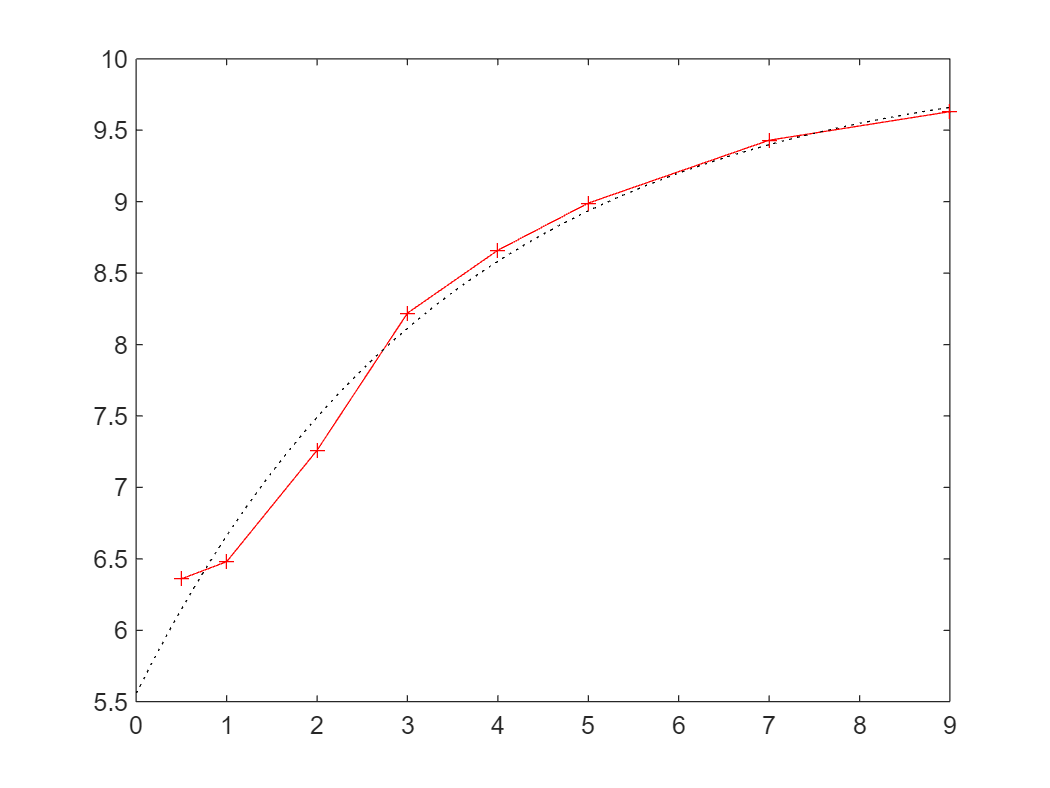

hold on
fplot(@(x)10-(10-arg.V).*exp(-x./arg.tau),[0,9],'k:')

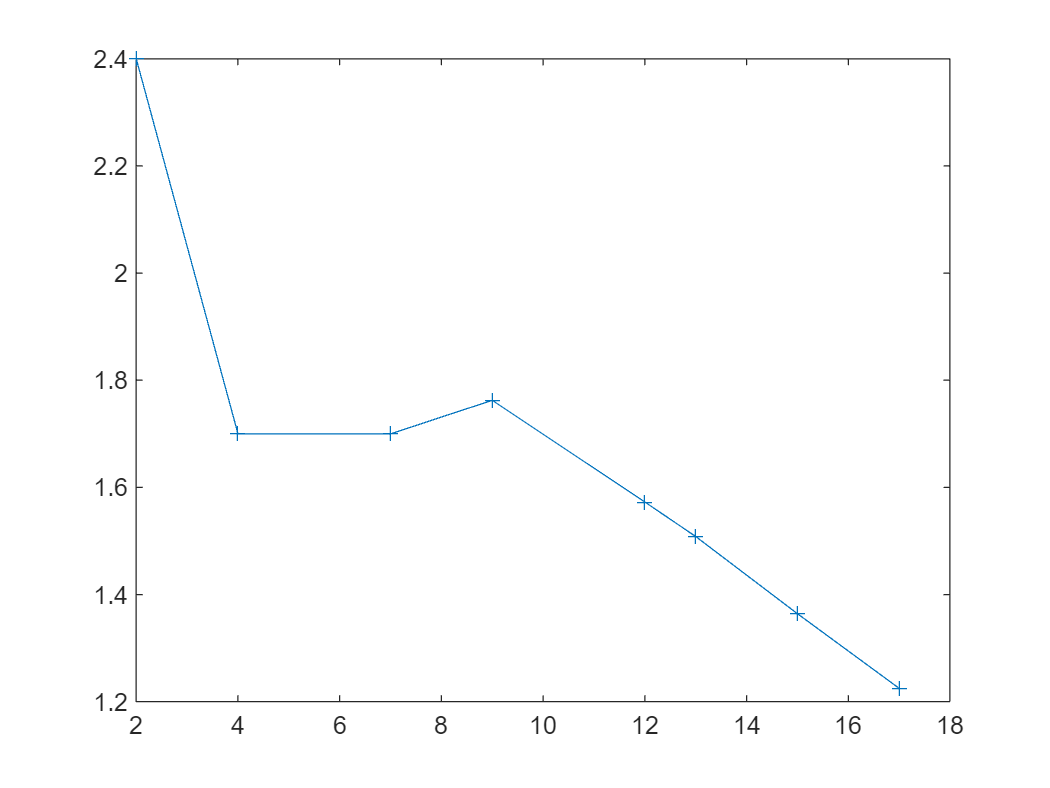

X = [1 2 4 7 9 12 13 15 17];
Y = [1.5 3.9 6.6 11.7 15.6 18.8 19.6 20.6 21.1];
Differences = (Y(1:end)-Y(1))./(X(1:end)-X(1));
clf
plot(X(1:end),Differences,"+-")

Notice that the quasi-derivative remains at the same value until x=9, and begins to decrease linearly after that.

Therefore, the function when hooke's law does not apply is probably a quodratic function.

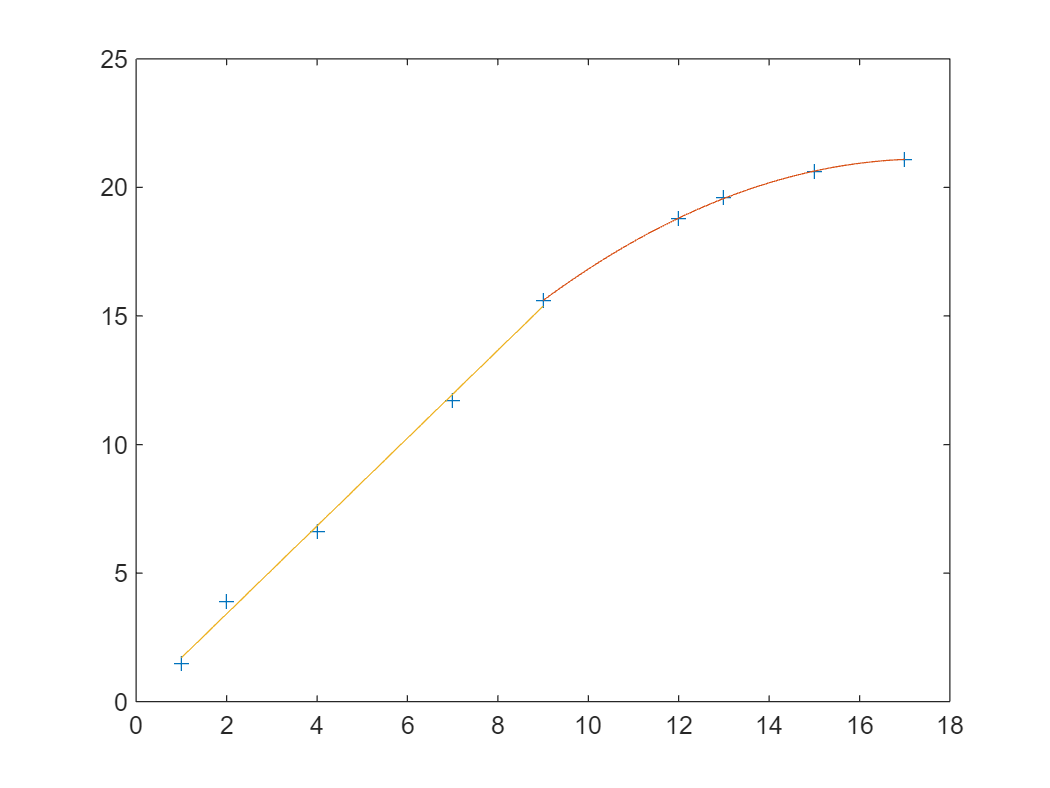

clf
plot(X,Y,"+")
hold on
p1 = polyfit(X(1:5),Y(1:5),1);
X1 = X(1):0.1:X(5);
Y1 = polyval(p1,X1);
p2 = polyfit(X(5:end),Y(5:end),2);
X2 = X(5):0.1:X(end);
Y2 = polyval(p2,X2);
plot(X2,Y2)
plot(X1,Y1)

Map = readmatrix("11月15日实验课实验题3的数据.xlsx");
Map(isnan(Map)) = 0;
size(Map)

ans =     14    16


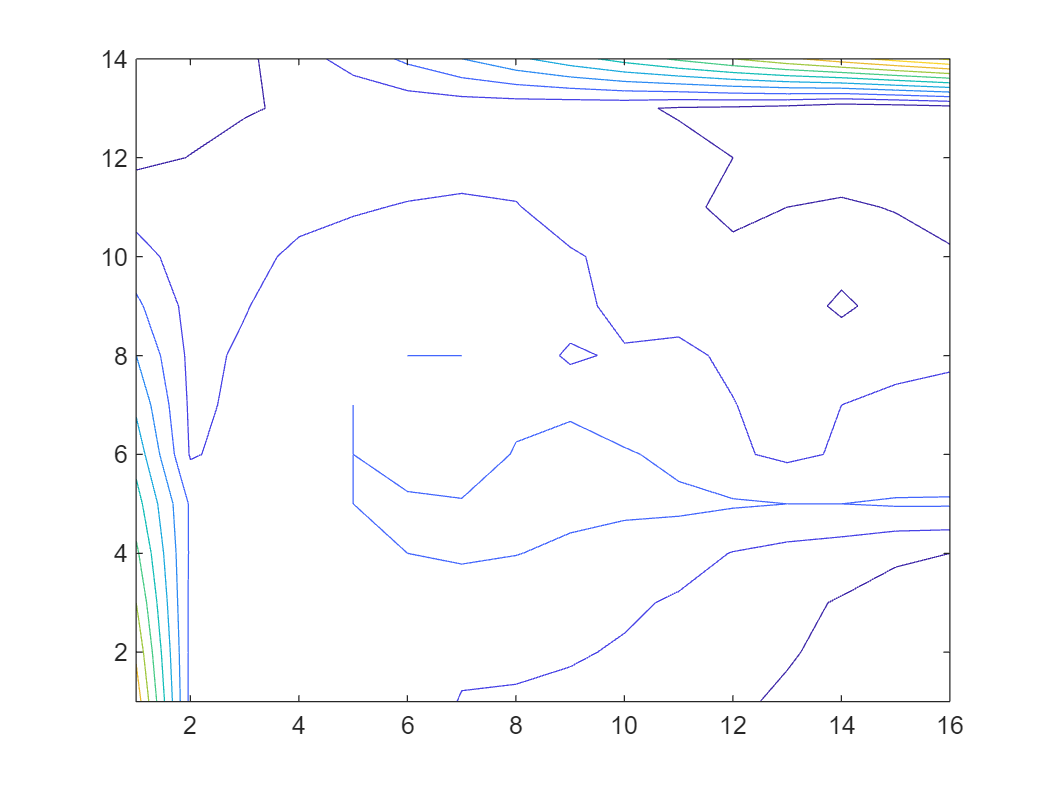

[X,Y] = meshgrid(1:15,1:13);
[Xq,Yq] = meshgrid(1:0.25:15,1:0.25:13);
MapQ = interp2(X,Y,Map(1:end-1,2:end),Xq,Yq,"spline");
clf
contour(Map)

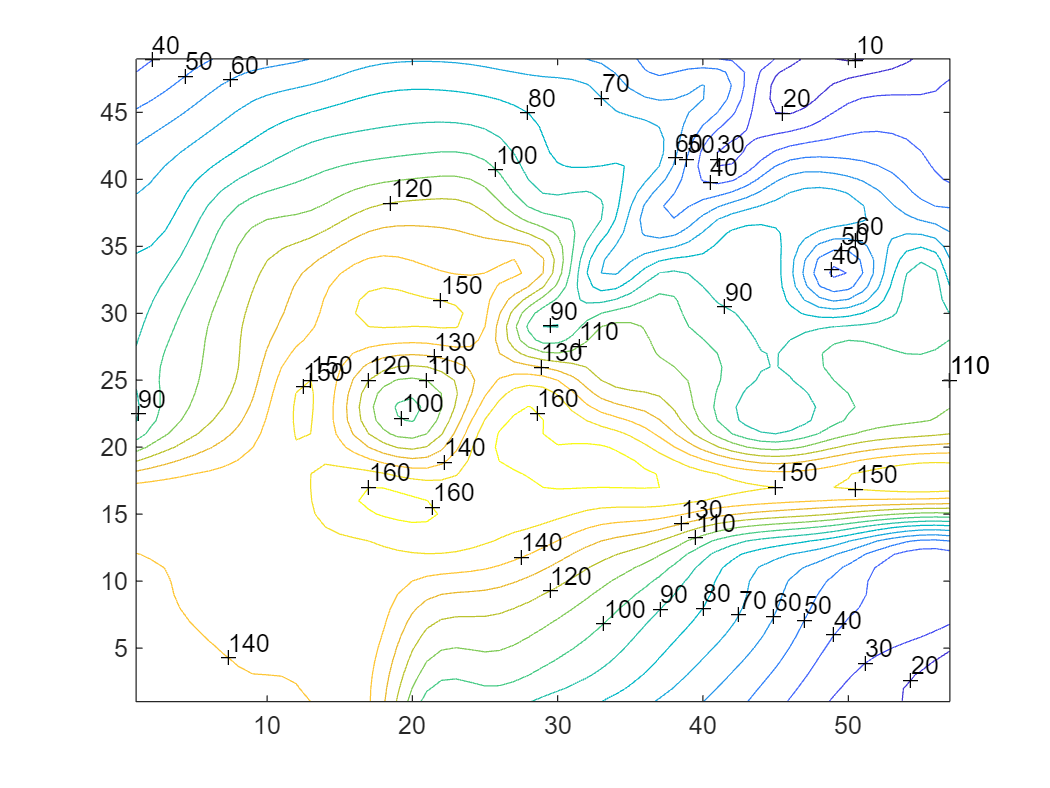

Q = contour(MapQ,0:10:160);
clabel(Q)

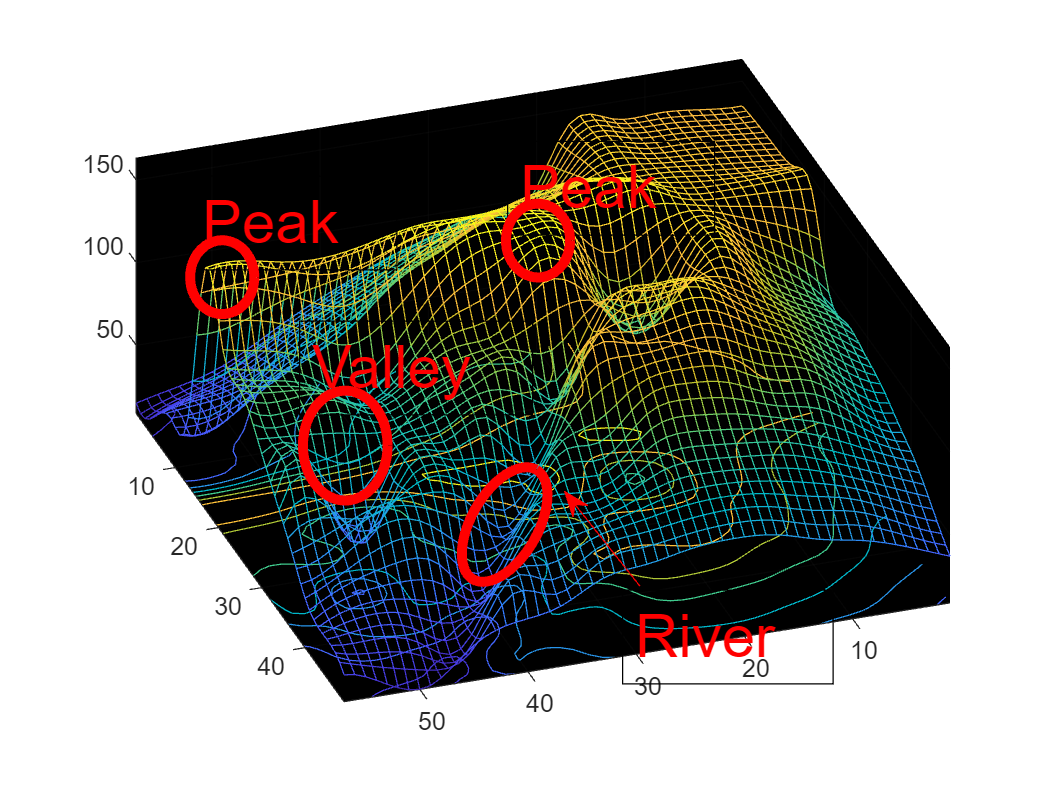


% 创建 figure
figure1 = figure('Name','Figure','Color',[1 1 1]);
clf
% 创建 axes
axes1 = axes('Parent',figure1);
hold(axes1,'on');

% % 创建 mesh
% mesh(xdata1,ydata1,zdata1);
% 
% % 创建 contour
% contour(xdata1,ydata1,zdata1,'ZLocation','zmin');
meshc(MapQ,"FaceColor","none")
set(gca,'color','k')

view(axes1,[161.073066850142 49.9622214846086]);
grid(axes1,'on');
axis(axes1,'tight');
hold(axes1,'off');
% 设置其余坐标区属性
set(axes1,'Color',[0 0 0]);
% 创建 textbox
annotation(figure1,'textbox',...
    [0.483500744047618 0.701537446903633 0.197023809523809 0.119047619047619],...
    'Color',[1 0 0],...
    'String',{'Peak'},...
    'FontSize',24,...
    'FitBoxToText','off');

% 创建 ellipse
annotation(figure1,'ellipse',...
    [0.481859375 0.647887323943652 0.0611093750000001 0.0936619718309801],...
    'Color',[1 0 0],...
    'LineWidth',4);

% 创建 textbox
annotation(figure1,'textbox',...
    [0.180859375 0.657417169684762 0.197023809523809 0.119047619047619],...
    'Color',[1 0 0],...
    'String',{'Peak'},...
    'FontSize',24,...
    'FitBoxToText','off');

% 创建 ellipse
annotation(figure1,'ellipse',...
    [0.181078125 0.601408450704219 0.061109375 0.0936619718309801],...
    'Color',[1 0 0],...
    'LineWidth',4);

% 创建 textbox
annotation(figure1,'textbox',...
    [0.285286458333332 0.473435501900279 0.222023809523811 0.119047619047617],...
    'Color',[1 0 0],...
    'String',{'Valley'},...
    'FontSize',24,...
    'FitBoxToText','off');

% 创建 ellipse
annotation(figure1,'ellipse',...
    [0.2885 0.364788732394366 0.0806406249999997 0.139436619718292],...
    'Color',[1 0 0],...
    'LineWidth',4);

% 创建 ellipse
annotation(figure1,'ellipse',...
    [0.477953125000001 0.243661971830979 0.120484374999998 0.0845070422535241],...
    'Color',[1 0 0],...
    'Rotation',60,...
    'LineWidth',4);

% 创建 arrow
annotation(figure1,'arrow',[0.609375 0.537890625],...
    [0.256338028169014 0.376056338028169],'Color',[1 0 0]);

% 创建 textbox
annotation(figure1,'textbox',...
    [0.592875744047618 0.132154482450253 0.200595238095238 0.119047619047618],...
    'Color',[1 0 0],...
    'String',{'River'},...
    'FontSize',24,...
    'FitBoxToText','off');